# Binomial distribution

## Physical Biology of the Cell: Day 2 (July 31 2018)

**Fun with random walkers! **

Let's set up a 1D walker starting at the origin who is constrained to move either left or right with equal probability. Essentially, we'll flip a coin and ask MATLAB to move the walker left for heads and right for tails.  How do we get MATLAB to flip a coin?

To have probability, we need to introduce random numbers!

number = rand()

number = 0.4396

We won't all get the same result, so our data might look different initially, but hopefully as we build up more "experiments" we can figure out a pattern.

First, we need to initialize some parameters about our walker:

position = 0; % initialize the position of the walker at 0
step_size = 1; % set the step size
prob_left = 0.5; % set the probability of taking a step to the left
prob_right = 1 - prob_left; % set the probability of taking a step to the right based on probability of going left

Draw a segment between 0 and 1 and show how we can get probability from this and coin flips. 

To take a step, we'll flip a coin, ask whether this means we step left or right, and then take the step! Since we only have two options, we can write the loop like this:

coin_flip = rand();
if coin_flip <= prob_left
    position = position - step_size;
else
    position = position + step_size;
end

If we had more than 2 options, we can use the "elseif" command. 

% coin_flip = rand();
% if coin_flip <= prob_left
%     position = position - step_size;
% elseif coin_flip > prob_right
%     position = position + step_size;
% end

So, now we've taken a single step from the origin. Not everyone moved left and not everyone moved right, but no one should be left at the origin.

position

position = -1

Let's track one walker and look at the trajectory over time. How do we write this loop? What do we need to keep track of?

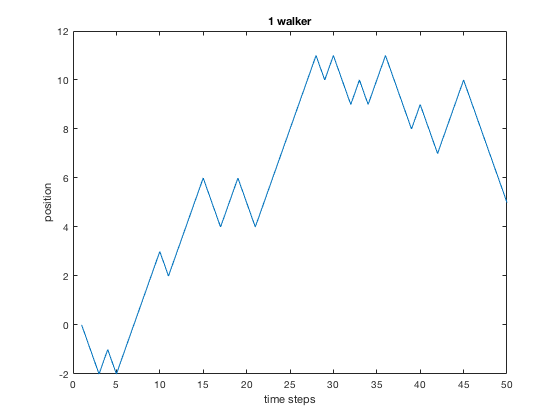

n_steps = 50;
step_size = 1; 
prob_left = 0.5;
position = zeros(1, n_steps);
for i = 2 : n_steps
    coin_flip = rand();
    if coin_flip <= prob_left
        position(i) = position(i-1) - step_size;
     else
         position(i) = position(i-1) + step_size;
    end
end

time = 1 : 1 : 50;
plot(time, position)
xlabel('time steps'); ylabel('position'); title('1 walker')

Now let's do this for a bunch of walkers over a bunch of time steps! How do we write pseudocode for this? How many loops will we need? What data will we need to keep track of? 

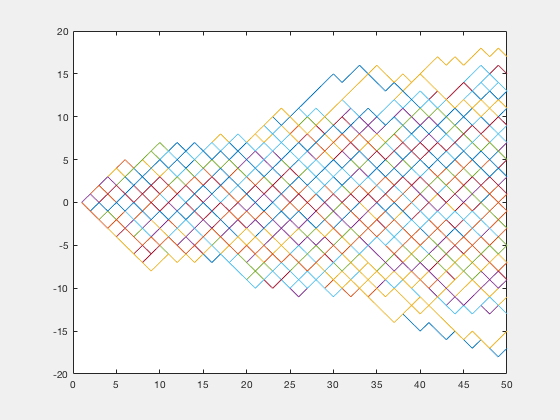

n_steps = 50;
n_walkers = 100;
prob_left = 0.5;
position = zeros(n_walkers, n_steps);

for i = 1 : n_walkers
    for j = 2 : n_steps
        coin_flip = rand();
        if coin_flip <= prob_left
            position(i, j) = position(i, j-1) - step_size;
         else
             position(i, j) = position(i, j-1) + step_size;
        end
    end
end

% pull this out into the command window (just copy and paste)
figure(1)
figure('visible', 'on'); 
time = 1 : 1 : n_steps;
for i = 1 : n_walkers
    plot(time, position(i, :))
    ylim([-20 20]); xlabel('time steps'); ylabel('position'); title('100 walkers')
    hold on
    drawnow
    pause(0.1)
end
hold off

Not sure what distribution that's giving us yet. What do we expect this result to be? (Go to board)

Let's figure out the mean displacement of the walkers at each time step: 

First, let's do this for one time point:

% to find all displacements after 1 step
displacement_one_step = zeros(1, n_walkers);
for i = 1 : n_walkers
    displacement_one_step(i) = position(i, 2) - position(i, 1);
end
meandisp_one_step = mean(displacement_one_step)

meandisp_one_step = 0.0400

Ok, now let's do it for all time intervals! (i.e. dt=1, dt=2, ... dt=50)

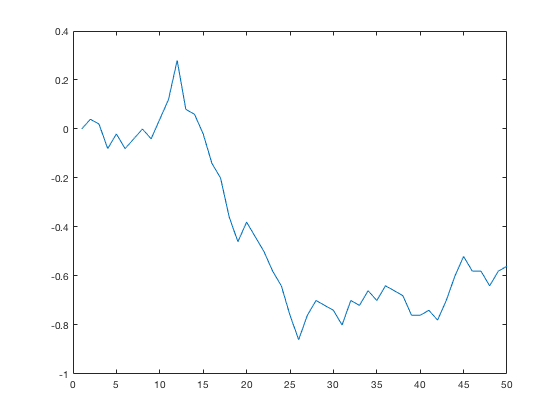

mean_disp = zeros(1, n_time_steps);

for i = 2 : n_time_steps
    mean_disp(i) = mean(position(:,i));
end

plot(mean_disp)

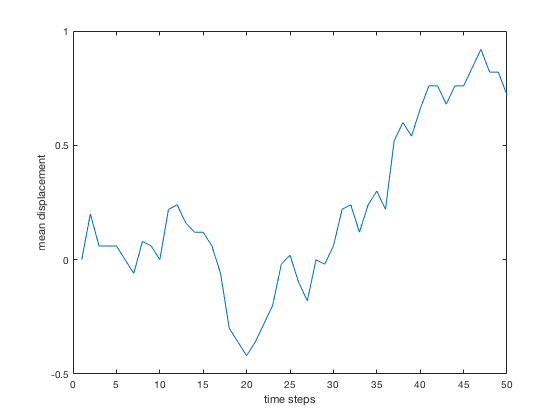


displacement_all_time_steps = zeros(n_steps, n_walkers);
for i = 2 : n_steps
    for j = 1 : n_walkers
        displacement_all_time_steps(i, j) = position(j, i) - position(j, 1);
    end
end

meandisp_all_steps = zeros(1, n_steps);
for i = 1 : n_steps
    meandisp_all_steps(i) = mean(displacement_all_time_steps(i,:));
end

time = 1 : 1 : n_steps;
plot(time, meandisp_all_steps)
xlabel('time steps'); ylabel('mean displacement')

What about mean squared displacement of the walkers? How do we do this?

- Find all displacements after 1 time step, square them, and average

- Do this for every step size

- Graph!

% to find all displacements after 1 step
displacement_one_step = zeros(1, n_walkers);
for i = 1 : n_walkers
    displacement_one_step(i) = position(i, 2) - position(i, 1);
end
sqdisp_one_step = displacement_one_step.^2;
meansqdisp_one_step = mean(sqdisp_one_step)

meansqdisp_one_step = 1

SANITY CHECK: is this what we expect? Go back to what we calculated on the board!

Ok, now let's do this for all the walkers for all possible time steps (i.e. dt=1, dt=2, ... dt=50)

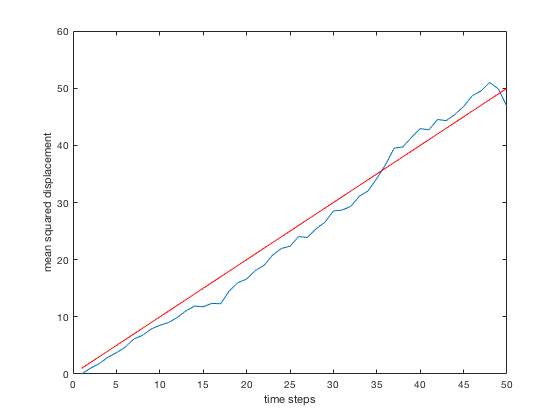

displacement_all_time_steps = zeros(n_steps, n_walkers);
for i = 2 : n_steps
    for j = 1 : n_walkers
        displacement_all_time_steps(i, j) = position(j, i) - position(j, 1);
    end
end

sqdisp_all_steps = displacement_all_time_steps.^2;

meansqdisp_all_steps = zeros(1, n_steps);
for i = 1 : n_steps
    meansqdisp_all_steps(i) = mean(sqdisp_all_steps(i,:));
end

time = 1 : 1 : n_steps;
plot(time, meansqdisp_all_steps)
hold on
expected_msd = 1 : 1 : n_steps;
plot(time, expected_msd, 'r')
xlabel('time steps'); ylabel('mean squared displacement')
hold off

Total displacement of the walkers over time: (lead into binomial distribution)

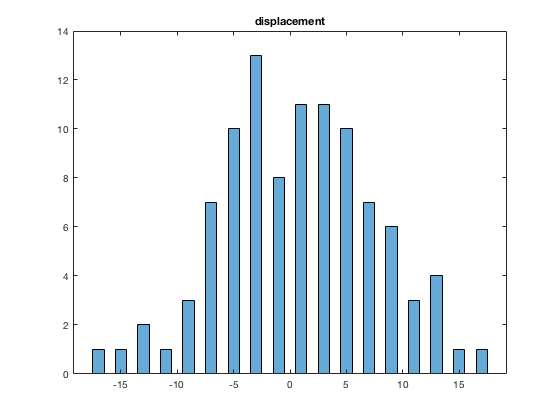

% total displacement of the walkers
movement = zeros(n_walkers, n_steps-1);
displacement = zeros(1, n_walkers);
for i = 1 : n_walkers
    for j = 1 : n_steps-1
        movement(i,j) = position(i, j+1) - position(i, j);
    end
    displacement(i) = sum(movement(i,:));
end
histogram(displacement); title('displacement')
hold off


% -> MAKE THIS INTO PROBABILITIES

**Coin flips!**

Let's flip a coin N times and see what the distribution of heads is.

prob_heads = 0.5;
n_flips = 50;
heads = zeros(1, n_flips);

for i = 1 : n_flips
    inst_flip = rand();
    if inst_flip <= prob_heads
        heads(i) = 1;
    else
        heads(i) = 0;
    end
end

n_heads = sum(heads)

n_heads = 27

Let's do this for lots of coins and then take a look at what the distribution is (introduce histograms!).

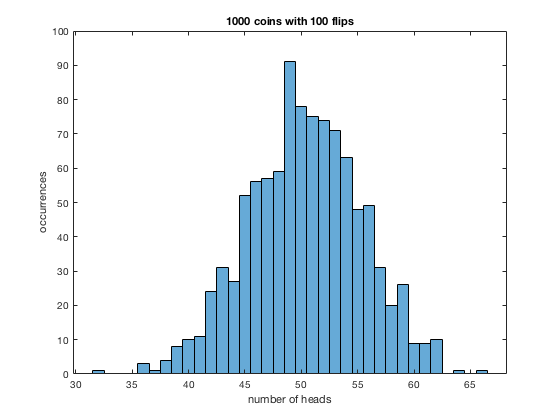

prob_heads = 0.5;
n_flips = 100;
n_coins = 1000;
heads = zeros(n_coins, n_flips);
n_heads = zeros(1, n_coins);

for i = 1 : n_coins
    for j = 1 : n_flips
        inst_flip = rand();
        if inst_flip <= prob_heads
            heads(i, j) = 1;
        else
            heads(i, j) = 0;
        end
    end
    n_heads(i) = sum(heads(i, :));
end
histogram(n_heads)
xlabel('number of heads'); ylabel('occurrences'); title('1000 coins with 100 flips')

Where does the histogram peak? (N/2)